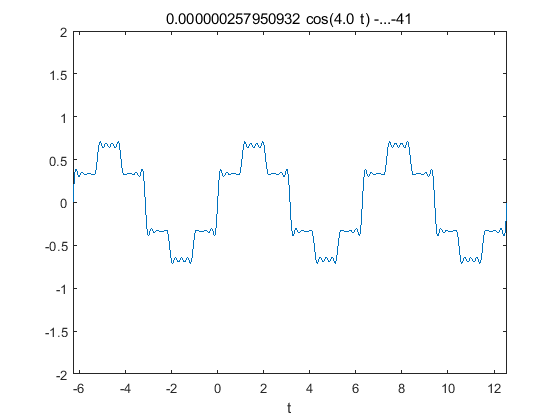

%Fourier Series Generater
%Formular a0 = 1/T  * int(f(t),t,0,T);
%Formular an = 2/T  * int(f(t)cos(n 2 pi 1/T t));
%Formular bn = 2/T  * int(f(t)sin(n 2 pi 1/T t));
%For the symbolic function

t = sym('t');
n = sym('n');
pis = sym('3.141');
T = 2*pis;
syms f(t);


%f = sym('1'); %needs to be a function of t
f(t) = piecewise( 0<t<=pis/3,1/3,pis/3<=t<2*pis/3,2/3,2*pis/3<=t<pis,1/3, pis<t<=4*pis/3,-1/3,4*pis/3<=t<5*pis/3,-2/3,5*pis/3<=t<2*pis,-1/3);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

w = 2*pis* (1/T);
order = 24;
x_min = -double(T);
x_max =2*double(T);
y_min= -2;
y_max =2;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

a0 = 1/T*int(f,t,0,T);
%disp('the value of a0 is:'); a0;
an = 2/T*int(f*cos(w*n*t),t,0,T);
%disp('the value of an is'); an;
bn = 2/T*int(f*sin(w*n*t),t,0,T);
%disp('the value of bn is'); bn;
%%parial sum
ps =  matlabFunction(vpa(an*cos(w*n*t)+bn*sin(w*n*t),10)); 
fs = vpa(matlabFunction( a0 + symsum(an*cos(w*n*t)+bn*sin(w*n*t),n,1,order)),10);

figure
ezplot(fs,[x_min,x_max,y_min,y_max]);

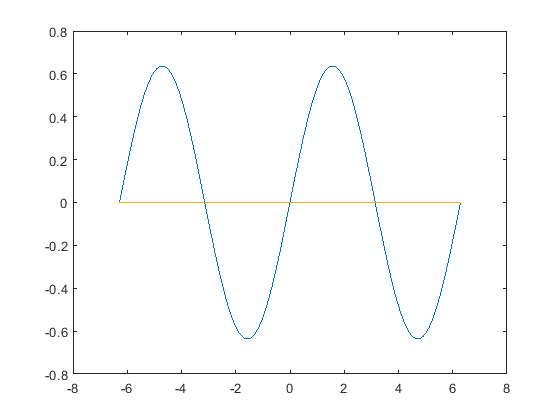

t = [double(-T):0.001:double(T)];
figure
plot(t,ps(1,t));
hold on;
plot(t,ps(2,t));
plot(t,ps(3,t));
hold off;

%where fs is function of x;